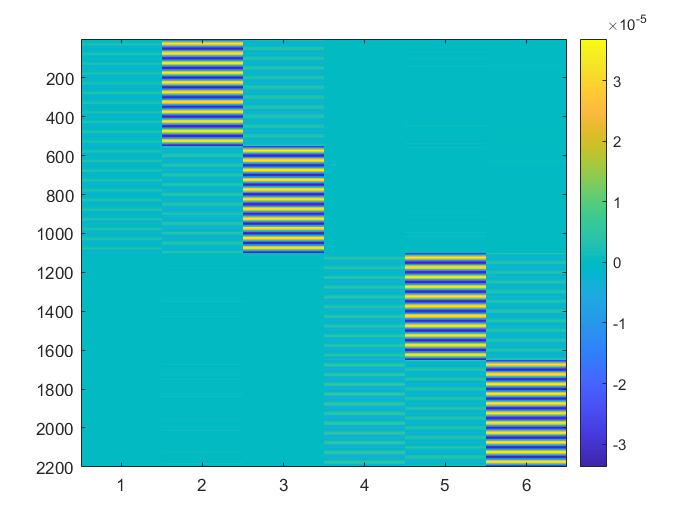

eqa = importdata('..//..//temp//simu86400//eqa_86400.txt'); 
diff_eqa = diff(eqa, 1, 1); diff_diff_eqa = diff(diff_eqa, 1, 1); diff_diff_diff_eqa = diff(diff_diff_eqa, 1, 1); diff_diff_diff_diff_eqa = diff(diff_diff_diff_eqa, 1, 1);
eqb = importdata('..//..//temp//simu86400//eqb_86400.txt'); diff_eqb = diff(eqb);

pc_a = [1.50; 0.00004; 0.00004];
pc_b = [1.50; 0.00004; 0.00004];

t = 0: 5: 86400 - 5;
alt_angle_sin = deg2rad(2 + 1 * sin(2 * pi / 250 * t))';
phase_centre_simu = pc_a(1) + pc_b(1) * cos(alt_angle_sin) - pc_b(3) * sin(alt_angle_sin); diff_simu = diff(phase_centre_simu); diff_diff_simu = diff(diff_simu); diff_diff_diff_simu = diff(diff_diff_simu); diff_diff_diff_diff_simu = diff(diff_diff_diff_simu);
phase_centre_simu = importdata('../../temp/simu86400/simu_86400.txt'); diff_simu = diff(phase_centre_simu); diff_diff_simu = diff(diff_simu);
% phase_centre_simu = eqa(:, 1: 3) * pc_b + eqa(:, 4: 6) * pc_a; diff_simu = diff(phase_centre_simu);
diff_eqb = diff_eqb + diff_simu;
diff_diff_eqb = diff(diff_eqb);
diff2_eqa = diff_diff_eqa; diff2_eqb = diff_diff_eqb;
diff3_eqb = diff(diff_diff_eqb); diff3_eqa = diff(diff_diff_eqa); diff3_simu = diff(diff_diff_simu);
diff4_eqb = diff(diff3_eqb); diff4_eqa = diff(diff3_eqa, 1, 1); diff4_simu = diff(diff3_simu);

start = 3001;
len = 600;
end_s = len + start - 1;
eqa1 = filter_pdfree(Num, diff3_eqa(start: end_s, [1 3 2 4 5 6]));
eqa2 = filter_pdfree(Num, diff3_eqa(end_s * 1 + 1: end_s * 1 + len, :));
eqa3 = filter_pdfree(Num, diff3_eqa(end_s * 2 + 1: end_s * 2 + len, [4 5 6 1 3 2]));
eqa4 = filter_pdfree(Num, diff3_eqa(end_s * 3 + 1: end_s * 3 + len, [4 5 6 1 2 3]));
eqb1 = filter_pdfree(Num, diff3_eqb(start: end_s));
eqb2 = filter_pdfree(Num, diff3_eqb(end_s*1 + 1: end_s*1 + len));
eqb3 = filter_pdfree(Num, diff3_eqb(end_s*2 + 1: end_s*2 + len));
eqb4 = filter_pdfree(Num, diff3_eqb(end_s*3 + 1: end_s*3 + len));
eqa_all = [eqa1; eqa2; eqa3; eqa4];
eqb_all = [eqb1; eqb2; eqb3; eqb4];
eqa_normal = eqa1' * eqa1 + eqa2' * eqa2 + eqa3' * eqa3 + eqa4' * eqa4;
eqb_normal = eqa1' * eqb1 + eqa2' * eqb2 + eqa3' * eqb3 + eqa4' * eqb4;

imagesc(eqa_all); colorbar

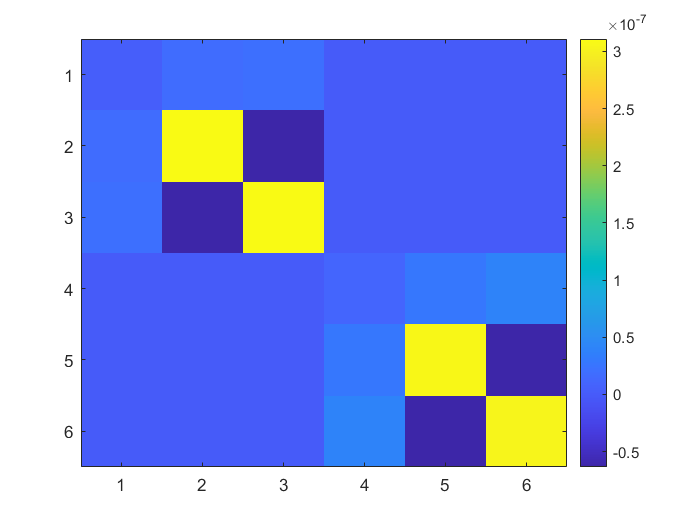

imagesc(eqa_normal); colorbar

cond(eqa_normal)

ans =     527.481860163575e+000


bbbb = lsqr(eqa_normal, eqb_normal)

lsqr converged at iteration 6 to a solution with relative residual 1.3e-07.


bbbb =     1.50587038012164e+000
   -461.069562101796e-006
   -408.097154490102e-006
    1.49990423272143e+000
    215.715887137232e-006
    82.0134294098138e-006


acos(dot(bbbb(1: 3), pc_a) / (norm(bbbb(1: 3)) * norm(pc_a)))

ans =     446.537534679801e-006


acos(dot(bbbb(4: 6), pc_b) / (norm(bbbb(4: 6)) * norm(pc_b)))

ans =     120.455582514611e-006


lsqr converged at iteration 1 to a solution with relative residual 0.021.
lsqr converged at iteration 1 to a solution with relative residual 0.021.
lsqr converged at iteration 1 to a solution with relative residual 0.021.
lsqr converged at iteration 1 to a solution with relative residual 0.009.
lsqr converged at iteration 1 to a solution with relative residual 0.009.
lsqr converged at iteration 1 to a solution with relative residual 0.009.
lsqr converged at iteration 1 to a solution with relative residual 0.025.
lsqr converged at iteration 1 to a solution with relative residual 0.025.
lsqr converged at iteration 1 to a solution with relative residual 0.025.


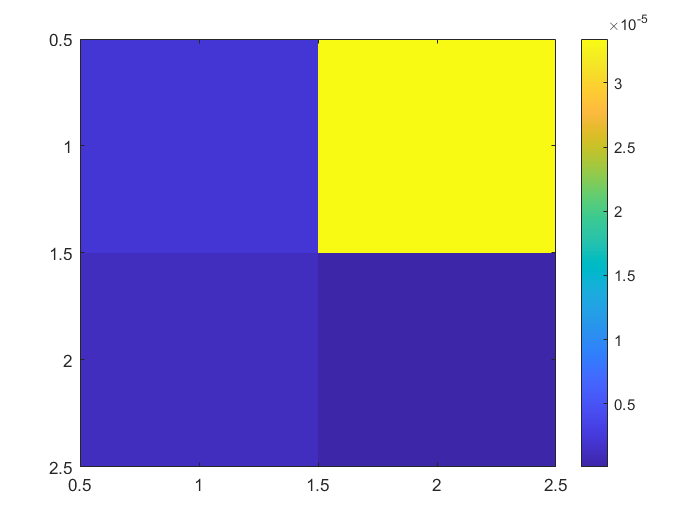

lsqr converged at iteration 2 to a solution with relative residual 2.6e-11.


cccc = zeros(6, 1);
cccc([1 2]) = solver_spectral(eqa1, eqb1, [1 2], 0.2);

lsqr converged at iteration 1 to a solution with relative residual 0.032.
lsqr converged at iteration 1 to a solution with relative residual 0.032.
lsqr converged at iteration 1 to a solution with relative residual 0.032.
lsqr converged at iteration 1 to a solution with relative residual 0.026.
lsqr converged at iteration 1 to a solution with relative residual 0.026.
lsqr converged at iteration 1 to a solution with relative residual 0.026.
lsqr converged at iteration 1 to a solution with relative residual 0.043.
lsqr converged at iteration 1 to a solution with relative residual 0.043.
lsqr converged at iteration 1 to a solution with relative residual 0.043.


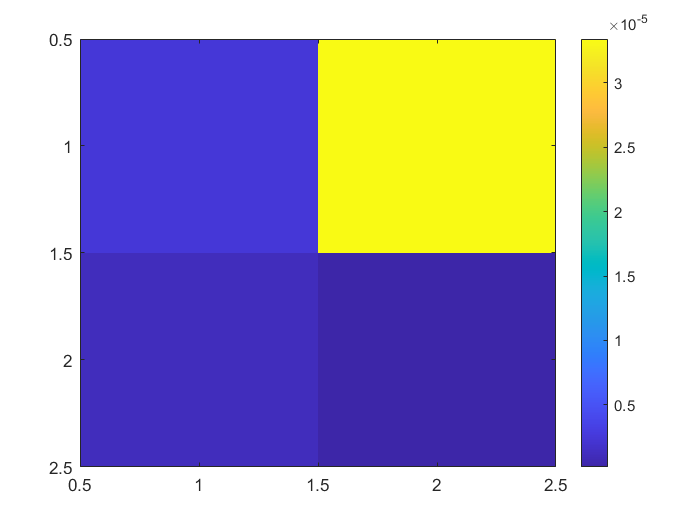

lsqr converged at iteration 2 to a solution with relative residual 2.4e-11.


cccc([1 3]) = solver_spectral(eqa2, eqb2, [1 3], 0.2);

lsqr converged at iteration 1 to a solution with relative residual 0.021.
lsqr converged at iteration 1 to a solution with relative residual 0.021.
lsqr converged at iteration 1 to a solution with relative residual 0.021.
lsqr converged at iteration 1 to a solution with relative residual 0.011.
lsqr converged at iteration 1 to a solution with relative residual 0.011.
lsqr converged at iteration 1 to a solution with relative residual 0.011.
lsqr converged at iteration 1 to a solution with relative residual 0.023.
lsqr converged at iteration 1 to a solution with relative residual 0.023.
lsqr converged at iteration 1 to a solution with relative residual 0.023.


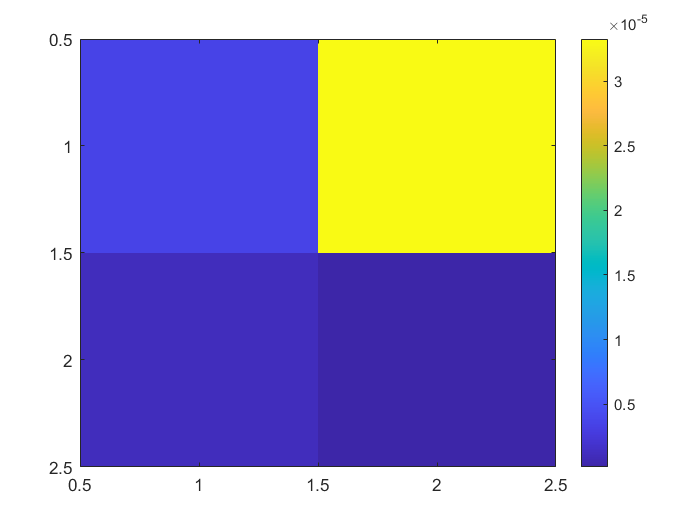

lsqr converged at iteration 2 to a solution with relative residual 9.1e-11.


cccc([4 5]) = solver_spectral(eqa3, eqb3, [4 5], 0.2);

lsqr converged at iteration 1 to a solution with relative residual 0.017.
lsqr converged at iteration 1 to a solution with relative residual 0.017.
lsqr converged at iteration 1 to a solution with relative residual 0.017.
lsqr converged at iteration 1 to a solution with relative residual 0.009.
lsqr converged at iteration 1 to a solution with relative residual 0.009.
lsqr converged at iteration 1 to a solution with relative residual 0.009.
lsqr converged at iteration 1 to a solution with relative residual 0.017.
lsqr converged at iteration 1 to a solution with relative residual 0.017.
lsqr converged at iteration 1 to a solution with relative residual 0.017.


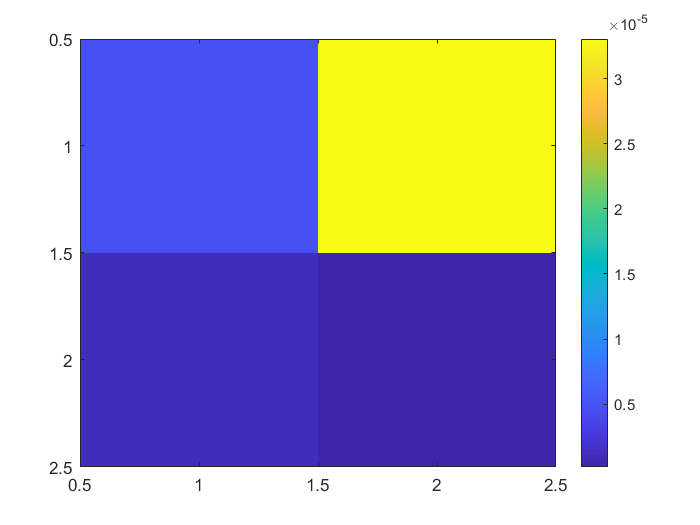

lsqr converged at iteration 2 to a solution with relative residual 3.6e-10.


cccc([4 6]) = solver_spectral(eqa4, eqb4, [4 6], 0.2);

cccc

cccc =     1.50596644792255e+000
   -409.170806442469e-006
   -365.653132964383e-006
    1.49838064133658e+000
    39.8892851382615e-006
    280.816538183348e-006


acos(dot(cccc(1: 3), pc_b) / (norm(cccc(1: 3)) * norm(pc_b)))

ans =     402.040336527958e-006


acos(dot(cccc(4: 6), pc_b) / (norm(cccc(4: 6)) * norm(pc_b)))

ans =     160.746688016608e-006
